close all;
clear all;
clc;
J=0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf("s");
sys = K/((J*s+b)*(L*s+R)+K^2);

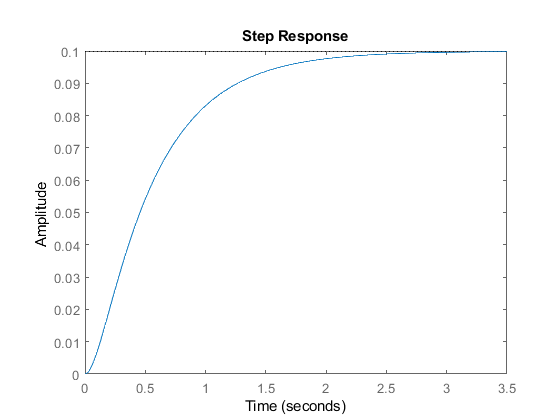

step(sys);

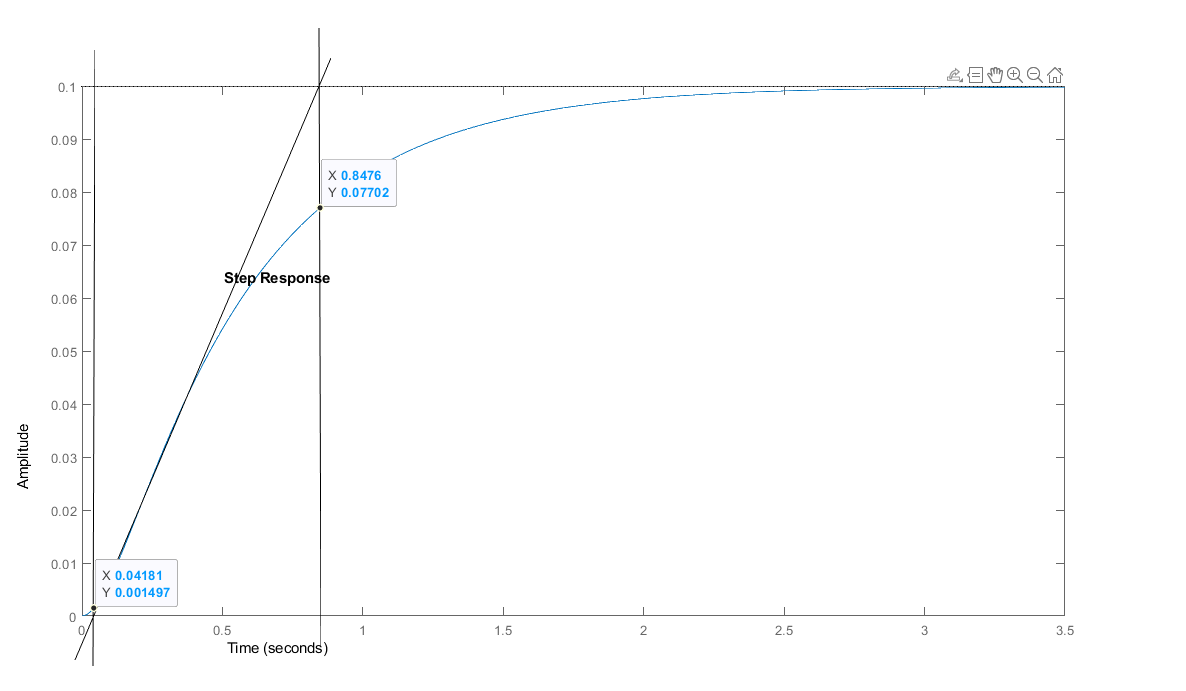

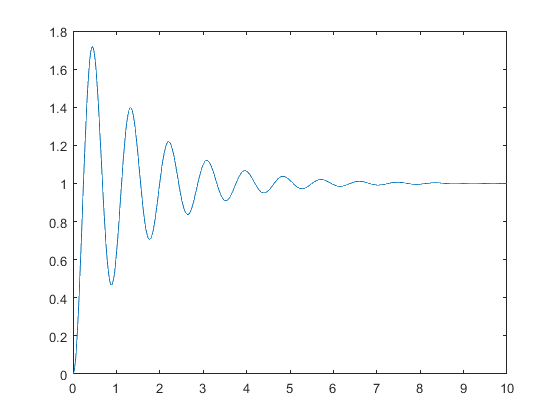

t = 0:0.01:10;
L = 0.04181;
K = 0.1;
T = 0.80579;  % 0.8476-0.04181
kp = round(1.2*T/L);   
ki = round(kp/(2*L)); 
kd = round(kp*L/2);    
y2 = drawFitness(sys, kp,ki,kd, t);
plot(t,y2);

%finding how many bits want for represent the population
maxK = max([kp,ki,kd]);
binK = dec2bin(maxK);
numOfBits = length(binK);